# 需求分析：散点拟合成圆的经典方法

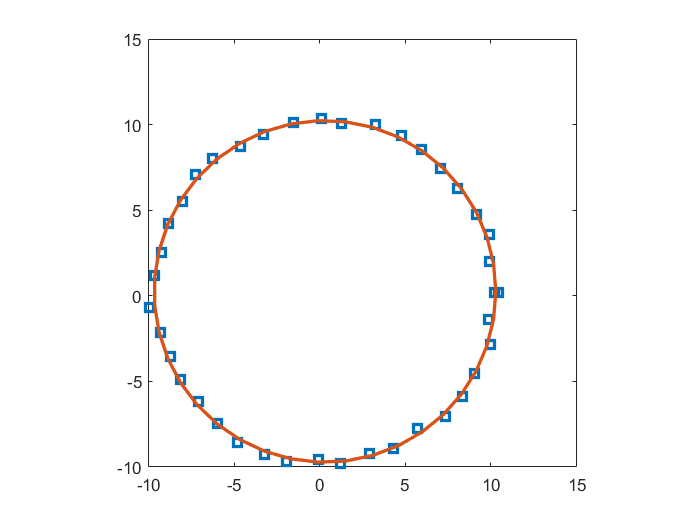

clear;clc;
M = 40;
theta = linspace(0, 2 * pi, M)';
r = 10;
ratio = 0.5;
x = r * cos(theta) + ratio * rand(M, 1);
y = r * sin(theta) + ratio * rand(M, 1);
xy = [x, y];
par = CircleFitByTaubin(xy);
x0 = par(1);
y0 = par(2);
r0 = par(3);
xfit = x0 + r0 * cos(theta);
yfit = y0 + r0 * sin(theta);
plot(x, y, 's', xfit ,yfit, 'linewidth', 2);
axis square